# 参数

clear,clc
%全交换面积计算参数
Lr = 3.8;%辐射管长度
Ws = 3.6;%钢板宽
Wfur = 3.9;%炉宽
epsilon_r = 0.8;%黑度
rho_r = 0.2;%反射率
epsilon_w = 0.5;
rho_w = 0.5;
epsilon_s = 0.75;
rho_s = 0.25;
epsilon_t = 0.9;
rho_t = 0.1;
%序号 直径 段长 h1 h2 辐射管间隔数组 功率数组 热电偶距段尾距离
cellZoneInfo = {1,0.3,8.7,0.65,0.91,[2700 600 600 600 600 600 1200 600 1200],[115 150 115 150 115 150 115 150 115/2],2.1;
         2,0.3,7.2,0.65,0.91,[600 600 600 600 600 600 600 600 600 600 600 600],[115/2 150 115 150 115 150 115 150 115 150 115 150 95/2],2.1;
         3,0.28,7.2,0.66,0.92,[600 600 600 600 600 600 1200 600 1200 600],[95/2 120 95 120 95 120 95 120 95 120 95/2],2.1;
         4,0.28,7.2,0.66,0.92,[600 2400 600 600 1200 600 600 600],[95/2 120 95 120 95 120 95 120 95/2],2.1;
         5,0.28,7.2,0.66,0.92,[600 1200 600 1200 600 1200 600 1200],[95/2 120 95 120 95 120 95 120 95/2],2.1;
         6,0.28,7.2,0.66,0.92,[1200 1200 1200 1200 1200 1200],[95/2 120 95 120 95 120 95/2],2.1;
         7,0.28,6.6,0.66,0.92,[1200 2400 1800 1200],[95/2 120 95 120 95/2],0.35;
         8,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[95/2 80 55 80 55/2],1.5;
         9,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2],1.5;
         10,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2],1.5;
         11,0.208,9.3,0.696,0.956,[1800 1800 1800 1800 2100],[55/2 80 55 120 95],2.4;}

cellZoneInfo = 11×8 cell 数组
    {[ 1]}    {[0.3000]}    {[8.7000]}    {[0.6500]}    {[0.9100]}    {[         2700 600 600 600 600 600 1200 600 1200]}    {[                    115 150 115 150 115 150 115 150 57.5000]}    {[2.1000]}
    {[ 2]}    {[0.3000]}    {[7.2000]}    {[0.6500]}    {[0.9100]}    {[600 600 600 600 600 600 600 600 600 600 600 600]}    {[57.5000 150 115 150 115 150 115 150 115 150 115 150 47.5000]}    {[2.1000]}
    {[ 3]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[      600 600 600 600 600 600 1200 600 1200 600]}    {[            47.5000 120 95 120 95 120 95 120 95 120 47.5000]}    {[2.1000]}
    {[ 4]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[              600 2400 600 600 1200 600 600 600]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}    {[2.1000]}
    {[ 5]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[            600 1200 600 1200 600 1200 600 1200]}    {[                   47.5000 120 95


ZonePosition = cell2mat(cellZoneInfo(:,3));
X = computeX(ZonePosition);%区域中点对应X坐标值

%三元法计算参数
%初(xia)始(gei)化区域温度场
Tw_init = [700 720 740 760 780 800 820 840 860 870 870] + 273.15 + 100;
Ts_1_init = [150 250 420 555 666 777 820 835 850 870 870] + 273.15;
% Ts_1_init = [350 550 620 755 866 977 1020 1035 1050 1070 1070] + 273.15;

Lfur = 82.2;%炉长,m
ths = 50/1000;%板厚,m
Time_heat = 80 * 60;%加热时间,s
Vs = Lfur / Time_heat;%物料速度
Thw = 0.35;%炉墙厚度
lambda_w = 0.135;%炉墙导热系数
% Cp_w = 1.12 * 1000;%炉墙比热 J/(kg*k)
% density_w = 190*250/300 + 128*50/300;%炉围密度
hw = 30;%炉墙综合换热系数
Temp_out = 30+273.15;%环境温度,k
density_s = 7860;
sigma = 5.67*10^(-8);%斯忒藩-玻尔兹曼常数
N = 10;%层数
s_timeStep = 800;%时间步长节点数

rt = 0.011;%热电偶半径
Ft = 4*pi*rt^2;

a1 = 1.465;%热电偶水平位置
a2 = 2.435;
c1 = 0.5 - ths;%热电偶距钢坯距离



# 全交换面积calc  1.2ver

- **1.0 ver:**单区域计算基本代码

- **1.1 ver:**循环计算多区域

- **1.2 ver:**热电偶全交换面积计算

**Todo:**辐射管黑度影响研究，完整性修正系数研究 

SR = zeros(1,length(cellZoneInfo));
SW = zeros(1,length(cellZoneInfo));
WR = zeros(1,length(cellZoneInfo));
RT = zeros(1,length(cellZoneInfo));
WT = zeros(1,length(cellZoneInfo));
ST = zeros(1,length(cellZoneInfo));


for i = 1:length(cellZoneInfo)

    %计算
    S = cellZoneInfo{i,6}./1000;%辐射管间隔数组
    d = cellZoneInfo{i,2};%辐射管直径
    L = cellZoneInfo{i,3};%段长
    h1 = cellZoneInfo{i,4};%见函数
    h2 = cellZoneInfo{i,5};
    kr = Lr/Wfur;%辐射管长度系数
    ks = Ws/Wfur;%钢板宽度系数

    c2 = cellZoneInfo{i,5} - c1;%热点偶距辐射管假想面距离
    b1 = cellZoneInfo{i,3} - cellZoneInfo{i,8};%热电偶距段头距离
    b2 = cellZoneInfo{i,8};%热电偶距段尾距离


    xrp = zeros(1,length(S));
    for j = 1:length(S)
        if S(j) == 2.7 || S(j) == 2.1
            xrp(j) = (d/2)/S(j)*atan(S(j)/(d/2));
        else
            xrp(j) = S(j)/(pi*d)*(1+d/S(j)*acos(d/S(j))-(1-(d/S(j))^2)^(1/2));
        end
    end
    %加权辐射管对假想面角系数
    Xrp = 0;
    for j = 1:length(xrp)
        Xrp = Xrp+S(j)/L*xrp(j);
    end
    %角系数

    Xp1w2 = phi_p1_w2(Wfur,L,h1) + phi_p2_w1(Wfur,L,h1);
    Xp2s = phi_p2_s(Wfur,L,h2);
    Xp2w1 = phi_p2_w1(Wfur,L,h2);
    
    % 论文中修正的角系数
    % Xrs = Xrp * 1/kr * Xp2s * ks;%计算Xrs
    Xrw = Xrp * 1/kr *Xp1w2 + Xrp * 1/kr *Xp2w1;
    Xrr = 1 - 2 * Xrp;%计算Xrr
    % Xrr = 1 - Xrw - Xrs;%完整性计算Xrr
    Xrs = 1 - Xrw - Xrr;%完整性计算Xrs
    
    %不修正的角系数
    % Xrs = Xrp * Xp2s ;
    % Xrw = Xrp *Xp1w2 + Xrp *Xp2w1;
    % Xrr = 1 - 2 * Xrp;

    Fs = L*Ws;
    Fw = L*Wfur+L*h1*2+L*h2*2;
    Fr = pi*d*length(S)*Lr;
    

    Xtp2 = (computeF(a1,b1,c2)*a1*b1 + computeF(a1,b2,c2)*a1*b2 + computeF(a2,b1,c2)*a2*b1 + computeF(a2,b2,c2)*a2*b2)/(L*Wfur);
    Xtp3 = (computeF(a1,b1,c1)*a1*b1 + computeF(a1,b2,c1)*a1*b2 + computeF(a2,b1,c1)*a2*b1 + computeF(a2,b2,c1)*a2*b2)/(L*Wfur);
    
    Xtr = Xrp * Xtp2 * kr;
    Xts = Xtp3 * ks;
    Xtw = 1 - Xtr - Xts;

    Xss= 0;
    Xsr = Xrs * Fr/Fs;
    Xsw = 1 - Xsr - Xss;
    Xwr = Xrw * Fr/Fw;
    Xws = Xsw * Fs/Fw;
    Xww = 1 - Xwr - Xws;
    %直接交换面积
    rr = Fr * Xrr;
    rw = Fr * Xrw;
    rs = Fr * Xrs;
    wr = Fw * Xwr;
    ww = Fw * Xww;
    ws = Fw * Xws;
    sr = Fs * Xsr;
    sw = Fs * Xsw;
    ss = Fs * Xss;

    %全交换面积

    RT(i) = -(Fr*epsilon_r*(Fs*Ft*Fw*Xtr*epsilon_t + Fs*Ft*Fw*Xrs*Xts*epsilon_t*rho_s + Fs*Ft*Fw*Xrw*Xtw*epsilon_t*rho_w - Fs*Ft*Fw*Xtr*Xww*epsilon_t*rho_w - Fs*Ft*Fw*Xtr*Xws^2*epsilon_t*rho_s*rho_w - Fs*Ft*Fw*Xrs*Xts*Xww*epsilon_t*rho_s*rho_w + Fs*Ft*Fw*Xrs*Xtw*Xws*epsilon_t*rho_s*rho_w + Fs*Ft*Fw*Xrw*Xts*Xws*epsilon_t*rho_s*rho_w))/(Fr*Fs*Fw*Xrr*rho_r - Fr*Fs*Fw + Fr*Fs*Fw*Xww*rho_w + Fr*Fs*Ft*Xtw^2*rho_t*rho_w + Fr*Fs*Fw*Xrw^2*rho_r*rho_w + Fr*Ft*Fw*Xts^2*rho_s*rho_t + Fs*Ft*Fw*Xtr^2*rho_r*rho_t + Fr*Fs*Fw*Xws^2*rho_s*rho_w + Fs^2*Fw*Xrs*Xsr*rho_r*rho_s - Fr*Fs*Fw*Xrr*Xww*rho_r*rho_w - Fr*Fs*Ft*Xrr*Xtw^2*rho_r*rho_t*rho_w - Fr*Ft*Fw*Xrr*Xts^2*rho_r*rho_s*rho_t - Fr*Fs*Fw*Xrr*Xws^2*rho_r*rho_s*rho_w - Fr*Ft*Fw*Xts^2*Xww*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xtr^2*Xww*rho_r*rho_t*rho_w - Fs^2*Fw*Xrs*Xsr*Xww*rho_r*rho_s*rho_w + Fs^2*Fw*Xrw*Xsr*Xws*rho_r*rho_s*rho_w - Fr*Ft*Fw*Xrw^2*Xts^2*rho_r*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xtr^2*Xws^2*rho_r*rho_s*rho_t*rho_w - Fs^2*Ft*Xrs*Xsr*Xtw^2*rho_r*rho_s*rho_t*rho_w + Fr*Fs*Ft*Xrw*Xtr*Xtw*rho_r*rho_t*rho_w + Fr*Fs*Fw*Xrs*Xrw*Xws*rho_r*rho_s*rho_w + Fs*Ft*Fw*Xrs*Xtr*Xts*rho_r*rho_s*rho_t + Fr*Fs*Ft*Xts*Xtw*Xws*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrw*Xtr*Xtw*rho_r*rho_t*rho_w + Fs*Ft*Fw*Xsr*Xtr*Xts*rho_r*rho_s*rho_t + Fr*Ft*Fw*Xts*Xtw*Xws*rho_s*rho_t*rho_w + Fr*Ft*Fw*Xrr*Xts^2*Xww*rho_r*rho_s*rho_t*rho_w + Fs^2*Ft*Xsr*Xtr*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fr*Fs*Ft*Xrs*Xrw*Xts*Xtw*rho_r*rho_s*rho_t*rho_w - Fr*Fs*Ft*Xrr*Xts*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrw*Xsr*Xts*Xtw*rho_r*rho_s*rho_t*rho_w - Fr*Ft*Fw*Xrr*Xts*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fr*Ft*Fw*Xrw*Xtr*Xts*Xws*rho_r*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xrs*Xtr*Xts*Xww*rho_r*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrs*Xtr*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrw*Xtr*Xts*Xws*rho_r*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xsr*Xtr*Xts*Xww*rho_r*rho_s*rho_t*rho_w);
    WT(i) = -(Ft*Fw*epsilon_t*epsilon_w*(Fr*Fs*Xtw - Fr*Fs*Xrr*Xtw*rho_r + Fr*Fs*Xrw*Xtr*rho_r + Fr*Fs*Xts*Xws*rho_s - Fs^2*Xrs*Xsr*Xtw*rho_r*rho_s + Fs^2*Xsr*Xtr*Xws*rho_r*rho_s + Fr*Fs*Xrs*Xrw*Xts*rho_r*rho_s - Fr*Fs*Xrr*Xts*Xws*rho_r*rho_s))/(Fr*Fs*Fw*Xrr*rho_r - Fr*Fs*Fw + Fr*Fs*Fw*Xww*rho_w + Fr*Fs*Ft*Xtw^2*rho_t*rho_w + Fr*Fs*Fw*Xrw^2*rho_r*rho_w + Fr*Ft*Fw*Xts^2*rho_s*rho_t + Fs*Ft*Fw*Xtr^2*rho_r*rho_t + Fr*Fs*Fw*Xws^2*rho_s*rho_w + Fs^2*Fw*Xrs*Xsr*rho_r*rho_s - Fr*Fs*Fw*Xrr*Xww*rho_r*rho_w - Fr*Fs*Ft*Xrr*Xtw^2*rho_r*rho_t*rho_w - Fr*Ft*Fw*Xrr*Xts^2*rho_r*rho_s*rho_t - Fr*Fs*Fw*Xrr*Xws^2*rho_r*rho_s*rho_w - Fr*Ft*Fw*Xts^2*Xww*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xtr^2*Xww*rho_r*rho_t*rho_w - Fs^2*Fw*Xrs*Xsr*Xww*rho_r*rho_s*rho_w + Fs^2*Fw*Xrw*Xsr*Xws*rho_r*rho_s*rho_w - Fr*Ft*Fw*Xrw^2*Xts^2*rho_r*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xtr^2*Xws^2*rho_r*rho_s*rho_t*rho_w - Fs^2*Ft*Xrs*Xsr*Xtw^2*rho_r*rho_s*rho_t*rho_w + Fr*Fs*Ft*Xrw*Xtr*Xtw*rho_r*rho_t*rho_w + Fr*Fs*Fw*Xrs*Xrw*Xws*rho_r*rho_s*rho_w + Fs*Ft*Fw*Xrs*Xtr*Xts*rho_r*rho_s*rho_t + Fr*Fs*Ft*Xts*Xtw*Xws*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrw*Xtr*Xtw*rho_r*rho_t*rho_w + Fs*Ft*Fw*Xsr*Xtr*Xts*rho_r*rho_s*rho_t + Fr*Ft*Fw*Xts*Xtw*Xws*rho_s*rho_t*rho_w + Fr*Ft*Fw*Xrr*Xts^2*Xww*rho_r*rho_s*rho_t*rho_w + Fs^2*Ft*Xsr*Xtr*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fr*Fs*Ft*Xrs*Xrw*Xts*Xtw*rho_r*rho_s*rho_t*rho_w - Fr*Fs*Ft*Xrr*Xts*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrw*Xsr*Xts*Xtw*rho_r*rho_s*rho_t*rho_w - Fr*Ft*Fw*Xrr*Xts*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fr*Ft*Fw*Xrw*Xtr*Xts*Xws*rho_r*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xrs*Xtr*Xts*Xww*rho_r*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrs*Xtr*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrw*Xtr*Xts*Xws*rho_r*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xsr*Xtr*Xts*Xww*rho_r*rho_s*rho_t*rho_w);
    ST(i) = -(Fs*Ft*epsilon_s*epsilon_t*(Fr*Fw*Xts - Fr*Fw*Xrr*Xts*rho_r + Fs*Fw*Xsr*Xtr*rho_r - Fr*Fw*Xts*Xww*rho_w + Fr*Fw*Xtw*Xws*rho_w - Fr*Fw*Xrw^2*Xts*rho_r*rho_w + Fs*Fw*Xrw*Xsr*Xtw*rho_r*rho_w + Fr*Fw*Xrr*Xts*Xww*rho_r*rho_w - Fr*Fw*Xrr*Xtw*Xws*rho_r*rho_w + Fr*Fw*Xrw*Xtr*Xws*rho_r*rho_w - Fs*Fw*Xsr*Xtr*Xww*rho_r*rho_w))/(Fr*Fs*Fw*Xrr*rho_r - Fr*Fs*Fw + Fr*Fs*Fw*Xww*rho_w + Fr*Fs*Ft*Xtw^2*rho_t*rho_w + Fr*Fs*Fw*Xrw^2*rho_r*rho_w + Fr*Ft*Fw*Xts^2*rho_s*rho_t + Fs*Ft*Fw*Xtr^2*rho_r*rho_t + Fr*Fs*Fw*Xws^2*rho_s*rho_w + Fs^2*Fw*Xrs*Xsr*rho_r*rho_s - Fr*Fs*Fw*Xrr*Xww*rho_r*rho_w - Fr*Fs*Ft*Xrr*Xtw^2*rho_r*rho_t*rho_w - Fr*Ft*Fw*Xrr*Xts^2*rho_r*rho_s*rho_t - Fr*Fs*Fw*Xrr*Xws^2*rho_r*rho_s*rho_w - Fr*Ft*Fw*Xts^2*Xww*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xtr^2*Xww*rho_r*rho_t*rho_w - Fs^2*Fw*Xrs*Xsr*Xww*rho_r*rho_s*rho_w + Fs^2*Fw*Xrw*Xsr*Xws*rho_r*rho_s*rho_w - Fr*Ft*Fw*Xrw^2*Xts^2*rho_r*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xtr^2*Xws^2*rho_r*rho_s*rho_t*rho_w - Fs^2*Ft*Xrs*Xsr*Xtw^2*rho_r*rho_s*rho_t*rho_w + Fr*Fs*Ft*Xrw*Xtr*Xtw*rho_r*rho_t*rho_w + Fr*Fs*Fw*Xrs*Xrw*Xws*rho_r*rho_s*rho_w + Fs*Ft*Fw*Xrs*Xtr*Xts*rho_r*rho_s*rho_t + Fr*Fs*Ft*Xts*Xtw*Xws*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrw*Xtr*Xtw*rho_r*rho_t*rho_w + Fs*Ft*Fw*Xsr*Xtr*Xts*rho_r*rho_s*rho_t + Fr*Ft*Fw*Xts*Xtw*Xws*rho_s*rho_t*rho_w + Fr*Ft*Fw*Xrr*Xts^2*Xww*rho_r*rho_s*rho_t*rho_w + Fs^2*Ft*Xsr*Xtr*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fr*Fs*Ft*Xrs*Xrw*Xts*Xtw*rho_r*rho_s*rho_t*rho_w - Fr*Fs*Ft*Xrr*Xts*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrw*Xsr*Xts*Xtw*rho_r*rho_s*rho_t*rho_w - Fr*Ft*Fw*Xrr*Xts*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fr*Ft*Fw*Xrw*Xtr*Xts*Xws*rho_r*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xrs*Xtr*Xts*Xww*rho_r*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrs*Xtr*Xtw*Xws*rho_r*rho_s*rho_t*rho_w + Fs*Ft*Fw*Xrw*Xtr*Xts*Xws*rho_r*rho_s*rho_t*rho_w - Fs*Ft*Fw*Xsr*Xtr*Xts*Xww*rho_r*rho_s*rho_t*rho_w);


    SR(i) = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr);
    SW(i) = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww);
    WR(i) = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww);
    
end
% SR = SR + 100;
% SW = SW + 100;
% WR = WR + 100;

RS = SR

RS =     8.1228   12.0070   10.1122    8.5713    8.5734    6.8275    4.8135    3.6980    3.6980    3.6980    3.8759


WS = SW

WS =    11.7324    5.7444    7.2096    8.3450    8.3433    9.5819    9.7744   11.7574   11.7574   11.7574   15.8011


RW = WR

RW =     7.9467   11.8279    9.8849    8.3148    8.3170    6.5717    4.5525    3.5549    3.5549    3.5549    3.8268


SR

SR =     8.1228   12.0070   10.1122    8.5713    8.5734    6.8275    4.8135    3.6980    3.6980    3.6980    3.8759


SW

SW =    11.7324    5.7444    7.2096    8.3450    8.3433    9.5819    9.7744   11.7574   11.7574   11.7574   15.8011


WR

WR =     7.9467   11.8279    9.8849    8.3148    8.3170    6.5717    4.5525    3.5549    3.5549    3.5549    3.8268



RT

RT = 1.0e-03 *

    0.3243    0.3726    0.3965    0.4142    0.4143    0.4336    0.4479    0.4669    0.4669    0.4669    0.3981


WT

WT = 1.0e-03 *

    0.8087    0.7754    0.7915    0.8035    0.8035    0.8173    0.8322    0.8486    0.8486    0.8486    0.8453


ST

ST = 1.0e-03 *

    0.3374    0.2402    0.2796    0.3111    0.3111    0.3458    0.3759    0.4018    0.4018    0.4018    0.4021


# 三元法calc   1.3ver

- **1.0 ver**:常物性计算基本代码

- **1.1 ver**:钢坯变物性计算追加

- **1.2 ver**:炉围常物性一维差分追加，施工中(**弃坑），**热电偶温度计算

- **1.3 ver**:插值热流求钢板升温

%初始化
Tw_zone = zeros(1,length(cellZoneInfo));
Tr_zone = zeros(1,length(cellZoneInfo));
Ts_zone = zeros(1,length(cellZoneInfo));
Tt_zone = zeros(1,length(cellZoneInfo));
Qs = zeros(1,length(cellZoneInfo));

phi_r = zeros(1,length(cellZoneInfo));

Temp_inlet = zeros(N+1,length(cellZoneInfo));
Temp_inlet(:,1) = 30 + 273.15;
Temp_total = zeros(length(cellZoneInfo),s_timeStep*length(cellZoneInfo));

% Nw = 5;

for i = 1:length(cellZoneInfo)

    phi_r(i) = sum(cellZoneInfo{i,7})*1000;%W
    Ts_1 = Ts_1_init(i);%段内物料表面初始温度
    Ts_2 = 0;%初始化，进循环用
    L = cellZoneInfo{i,3};%段长
    Time_zone = L / Vs;%段内时间

    Tw_1 = Tw_init(i);
    Tw_2 = 0;%初始化，进循环
    
    
    while(abs((Ts_2 - Ts_1)/Ts_1)>=0.001)

        Ts_1 = Ts_2;%迭代

        while (abs((Tw_2 - Tw_1)/Tw_1)>=0.001)

            Tw_1 = Tw_2;%迭代

        %能量平衡解Tr
            syms Tr;
            f1 = sigma*RW(i)*(Tr^4 - Tw_1^4) + sigma*RS(i)*(Tr^4 - Ts_1^4) == phi_r(i);
            Tr = solve(f1,Tr);
            Tr = vpa(Tr);
            Tr= Tr(imag(Tr) == 0 & real(Tr) > 0);
    
        %能量平衡解Tw   
            syms Tw_2;
            f2 = sigma*SW(i)*(Ts_1^4 - Tw_2^4) + sigma*RW(i)*(Tr^4 - Tw_2^4) == Fw*(Tw_2 - Temp_out)/(1/hw+Thw/lambda_w);
            Tw_2 = solve(f2,Tw_2);
            Tw_2 = vpa(Tw_2);
            Tw_2= Tw_2(imag(Tw_2) == 0 & real(Tw_2) > 0);
        end
        
        Tw_1 = Tw_2;

    %差分求炉围温度(弃坑
        % Tw_zone_init = zeros(1,Nw+1) + Tw_1;
        % while(abs((Tw_2 - Tw_1)/Tw_1)>=0.01)
        %     qw_in = abs(sigma*SW(i)*(Ts_1^4 - Tw_1^4) + sigma*RW(i)*(Tr^4 - Tw_1^4));
        %     qw_out = 
        % end


    %求钢坯表面热流    
        qcon_s = -(sigma*RS(i)*(Ts_1^4 - Tr^4) + sigma*WS(i)*(Ts_1^4 - Tw_1^4))/Fs;%钢坯表面热流密度
        % RS(i)*(Ts_1^4 - Tr^4)
        % WS(i)*(Ts_1^4 - Tw_1^4)
    %差分求物料温度   
        T = Temp_inlet(:,i);
        delta_t = Time_zone / s_timeStep;%时间步长
        delta_x = ths/(2*N);%空间步长
        Temp_zone = zeros(length(cellZoneInfo),s_timeStep);
        for j = 1:s_timeStep
            T = TDMA_s(qcon_s,N,density_s,delta_t,delta_x,T);
            Temp_zone(:,j) = T;
        end
    
        Ts_2 = sum(Temp_zone(1,:))/s_timeStep;%热流反算物料表面温度
    
        % if abs((Ts_2 - Ts_1)/Ts_1)<=0.001
        %     break;
        % end
        Tw_2 = 0;%进循环

    end
    
    % sprintf('%.3e', phi_r(i)/sigma)
    % sprintf('%.3e', RW(i)*Tw^4)
    % sprintf('%.3e', RS(i)*Ts_2^4)

    syms Tt;
    f1 = sigma*RT(i)*(Tr^4 - Tt^4) + sigma*WT(i)*(Tw_1^4 - Tt^4) + sigma*ST(i)*(Ts_2^4 - Tt^4)== 0;
    Tt = solve(f1,Tt);
    Tt = vpa(Tt);
    Tt = Tt(imag(Tt) == 0 & real(Tt) > 0);
    Tt_zone(i) = Tt;%K

    Temp_inlet(:,i+1) = T
    Tw_zone(i) = Tw_1 ;%K
    Tr_zone(i) = Tr ;%K
    Ts_zone(i) = Ts_2 ;%K
    Temp_total(:,1+(i-1)*s_timeStep:i*s_timeStep) = Temp_zone;%K

    Qs(i) = qcon_s; 

end

Temp_inlet =   303.1500  475.6195         0         0         0         0         0         0         0         0         0
  303.1500  473.7525         0         0         0         0         0         0         0         0         0
  303.1500  472.0869         0         0         0         0         0         0         0         0         0
  303.1500  470.6210         0         0         0         0         0         0         0         0         0
  303.1500  469.3534         0         0         0         0         0         0         0         0         0
  303.1500  468.2829         0         0         0         0         0         0         0         0         0
  303.1500  467.4085         0         0         0         0         0         0         0         0         0
  303.1500  466.7292         0         0         0         0         0         0         0         0         0
  303.1500  466.2445         0         0         0         0         0         0         0         

Temp_inlet =   303.1500  475.6195  659.6313         0         0         0         0         0         0         0         0
  303.1500  473.7525  656.5112         0         0         0         0         0         0         0         0
  303.1500  472.0869  653.7333         0         0         0         0         0         0         0         0
  303.1500  470.6210  651.2928         0         0         0         0         0         0         0         0
  303.1500  469.3534  649.1857         0         0         0         0         0         0         0         0
  303.1500  468.2829  647.4085         0         0         0         0         0         0         0         0
  303.1500  467.4085  645.9583         0         0         0         0         0         0         0         0
  303.1500  466.7292  644.8328         0         0         0         0         0         0         0         0
  303.1500  466.2445  644.0302         0         0         0         0         0         0         

Temp_inlet =   303.1500  475.6195  659.6313  767.4136         0         0         0         0         0         0         0
  303.1500  473.7525  656.5112  765.0346         0         0         0         0         0         0         0
  303.1500  472.0869  653.7333  762.9201         0         0         0         0         0         0         0
  303.1500  470.6210  651.2928  761.0651         0         0         0         0         0         0         0
  303.1500  469.3534  649.1857  759.4656         0         0         0         0         0         0         0
  303.1500  468.2829  647.4085  758.1181         0         0         0         0         0         0         0
  303.1500  467.4085  645.9583  757.0195         0         0         0         0         0         0         0
  303.1500  466.7292  644.8328  756.1675         0         0         0         0         0         0         0
  303.1500  466.2445  644.0302  755.5602         0         0         0         0         0         

Temp_inlet =   303.1500  475.6195  659.6313  767.4136  845.9831         0         0         0         0         0         0
  303.1500  473.7525  656.5112  765.0346  843.9153         0         0         0         0         0         0
  303.1500  472.0869  653.7333  762.9201  842.0711         0         0         0         0         0         0
  303.1500  470.6210  651.2928  761.0651  840.4486         0         0         0         0         0         0
  303.1500  469.3534  649.1857  759.4656  839.0458         0         0         0         0         0         0
  303.1500  468.2829  647.4085  758.1181  837.8615         0         0         0         0         0         0
  303.1500  467.4085  645.9583  757.0195  836.8941         0         0         0         0         0         0
  303.1500  466.7292  644.8328  756.1675  836.1428         0         0         0         0         0         0
  303.1500  466.2445  644.0302  755.5602  835.6067         0         0         0         0         

Temp_inlet =   303.1500  475.6195  659.6313  767.4136  845.9831  923.2726         0         0         0         0         0
  303.1500  473.7525  656.5112  765.0346  843.9153  921.0978         0         0         0         0         0
  303.1500  472.0869  653.7333  762.9201  842.0711  919.1511         0         0         0         0         0
  303.1500  470.6210  651.2928  761.0651  840.4486  917.4329         0         0         0         0         0
  303.1500  469.3534  649.1857  759.4656  839.0458  915.9433         0         0         0         0         0
  303.1500  468.2829  647.4085  758.1181  837.8615  914.6825         0         0         0         0         0
  303.1500  467.4085  645.9583  757.0195  836.8941  913.6507         0         0         0         0         0
  303.1500  466.7292  644.8328  756.1675  836.1428  912.8481         0         0         0         0         0
  303.1500  466.2445  644.0302  755.5602  835.6067  912.2747         0         0         0         

Temp_inlet =   303.1500  475.6195  659.6313  767.4136  845.9831  923.2726  978.1093         0         0         0         0
  303.1500  473.7525  656.5112  765.0346  843.9153  921.0978  976.5025         0         0         0         0
  303.1500  472.0869  653.7333  762.9201  842.0711  919.1511  975.0643         0         0         0         0
  303.1500  470.6210  651.2928  761.0651  840.4486  917.4329  973.7951         0         0         0         0
  303.1500  469.3534  649.1857  759.4656  839.0458  915.9433  972.6948         0         0         0         0
  303.1500  468.2829  647.4085  758.1181  837.8615  914.6825  971.7636         0         0         0         0
  303.1500  467.4085  645.9583  757.0195  836.8941  913.6507  971.0016         0         0         0         0
  303.1500  466.7292  644.8328  756.1675  836.1428  912.8481  970.4089         0         0         0         0
  303.1500  466.2445  644.0302  755.5602  835.6067  912.2747  969.9854         0         0         

Temp_inlet = 1.0e+03 *

    0.3031    0.4756    0.6596    0.7674    0.8460    0.9233    0.9781    1.0103         0         0         0
    0.3031    0.4738    0.6565    0.7650    0.8439    0.9211    0.9765    1.0092         0         0         0
    0.3031    0.4721    0.6537    0.7629    0.8421    0.9192    0.9751    1.0083         0         0         0
    0.3031    0.4706    0.6513    0.7611    0.8404    0.9174    0.9738    1.0075         0         0         0
    0.3031    0.4694    0.6492    0.7595    0.8390    0.9159    0.9727    1.0067         0         0         0
    0.3031    0.4683    0.6474    0.7581    0.8379    0.9147    0.9718    1.0061         0         0         0
    0.3031    0.4674    0.6460    0.7570    0.8369    0.9137    0.9710    1.0056         0         0         0
    0.3031    0.4667    0.6448    0.7562    0.8361    0.9128    0.9704    1.0053         0         0         0
    0.3031    0.4662    0.6440    0.7556    0.8356    0.9123    0.9700    1.0050        

Temp_inlet = 1.0e+03 *

    0.3031    0.4756    0.6596    0.7674    0.8460    0.9233    0.9781    1.0103    1.0336         0         0
    0.3031    0.4738    0.6565    0.7650    0.8439    0.9211    0.9765    1.0092    1.0329         0         0
    0.3031    0.4721    0.6537    0.7629    0.8421    0.9192    0.9751    1.0083    1.0323         0         0
    0.3031    0.4706    0.6513    0.7611    0.8404    0.9174    0.9738    1.0075    1.0317         0         0
    0.3031    0.4694    0.6492    0.7595    0.8390    0.9159    0.9727    1.0067    1.0313         0         0
    0.3031    0.4683    0.6474    0.7581    0.8379    0.9147    0.9718    1.0061    1.0309         0         0
    0.3031    0.4674    0.6460    0.7570    0.8369    0.9137    0.9710    1.0056    1.0305         0         0
    0.3031    0.4667    0.6448    0.7562    0.8361    0.9128    0.9704    1.0053    1.0303         0         0
    0.3031    0.4662    0.6440    0.7556    0.8356    0.9123    0.9700    1.0050    1.03

Temp_inlet = 1.0e+03 *

    0.3031    0.4756    0.6596    0.7674    0.8460    0.9233    0.9781    1.0103    1.0336    1.0561         0
    0.3031    0.4738    0.6565    0.7650    0.8439    0.9211    0.9765    1.0092    1.0329    1.0555         0
    0.3031    0.4721    0.6537    0.7629    0.8421    0.9192    0.9751    1.0083    1.0323    1.0549         0
    0.3031    0.4706    0.6513    0.7611    0.8404    0.9174    0.9738    1.0075    1.0317    1.0544         0
    0.3031    0.4694    0.6492    0.7595    0.8390    0.9159    0.9727    1.0067    1.0313    1.0540         0
    0.3031    0.4683    0.6474    0.7581    0.8379    0.9147    0.9718    1.0061    1.0309    1.0536         0
    0.3031    0.4674    0.6460    0.7570    0.8369    0.9137    0.9710    1.0056    1.0305    1.0533         0
    0.3031    0.4667    0.6448    0.7562    0.8361    0.9128    0.9704    1.0053    1.0303    1.0531         0
    0.3031    0.4662    0.6440    0.7556    0.8356    0.9123    0.9700    1.0050    1.03

Temp_inlet = 1.0e+03 *

    0.3031    0.4756    0.6596    0.7674    0.8460    0.9233    0.9781    1.0103    1.0336    1.0561    1.0788
    0.3031    0.4738    0.6565    0.7650    0.8439    0.9211    0.9765    1.0092    1.0329    1.0555    1.0781
    0.3031    0.4721    0.6537    0.7629    0.8421    0.9192    0.9751    1.0083    1.0323    1.0549    1.0776
    0.3031    0.4706    0.6513    0.7611    0.8404    0.9174    0.9738    1.0075    1.0317    1.0544    1.0771
    0.3031    0.4694    0.6492    0.7595    0.8390    0.9159    0.9727    1.0067    1.0313    1.0540    1.0766
    0.3031    0.4683    0.6474    0.7581    0.8379    0.9147    0.9718    1.0061    1.0309    1.0536    1.0763
    0.3031    0.4674    0.6460    0.7570    0.8369    0.9137    0.9710    1.0056    1.0305    1.0533    1.0760
    0.3031    0.4667    0.6448    0.7562    0.8361    0.9128    0.9704    1.0053    1.0303    1.0531    1.0758
    0.3031    0.4662    0.6440    0.7556    0.8356    0.9123    0.9700    1.0050    1.03

Temp_inlet = 1.0e+03 *

    0.3031    0.4756    0.6596    0.7674    0.8460    0.9233    0.9781    1.0103    1.0336    1.0561    1.0788    1.1215
    0.3031    0.4738    0.6565    0.7650    0.8439    0.9211    0.9765    1.0092    1.0329    1.0555    1.0781    1.1206
    0.3031    0.4721    0.6537    0.7629    0.8421    0.9192    0.9751    1.0083    1.0323    1.0549    1.0776    1.1198
    0.3031    0.4706    0.6513    0.7611    0.8404    0.9174    0.9738    1.0075    1.0317    1.0544    1.0771    1.1191
    0.3031    0.4694    0.6492    0.7595    0.8390    0.9159    0.9727    1.0067    1.0313    1.0540    1.0766    1.1185
    0.3031    0.4683    0.6474    0.7581    0.8379    0.9147    0.9718    1.0061    1.0309    1.0536    1.0763    1.1180
    0.3031    0.4674    0.6460    0.7570    0.8369    0.9137    0.9710    1.0056    1.0305    1.0533    1.0760    1.1176
    0.3031    0.4667    0.6448    0.7562    0.8361    0.9128    0.9704    1.0053    1.0303    1.0531    1.0758    1.1172
    0.30

Tw_zone - 273.15%各段温度

ans =   616.2726  785.6947  726.8179  724.7824  769.2593  777.8385  784.3770  784.2500  802.8564  823.6139  858.0202


Tr_zone - 273.15

ans =   842.2164  892.2615  846.6475  851.5392  883.4358  894.9775  903.5175  896.7424  904.2378  920.2607  973.8026


Ts_zone - 273.15

ans =   119.9585  297.5532  439.7113  533.1672  611.7132  676.6313  720.1252  748.1860  771.6172  794.2900  827.4485


Tt_zone - 273.15

ans =   638.5983  776.8598  730.1443  736.8904  780.0082  795.9485  808.3294  811.0207  826.7608  846.2697  882.6461


Temp_zone(1,s_timeStep) - 273.15 %物料出炉温度

ans = 848.3022

Temp_total = Temp_total - 273.15;%钢温温度场
Qs%热流

Qs = 1.0e+04 *

    3.2921    4.6548    3.1556    2.5120    2.5079    1.8678    1.2239    0.8077    0.7465    0.7449    1.0636




%插值热流求钢板升温
T_total = Temp_inlet(:,1);
delta_t_total = Time_heat / (s_timeStep * length(cellZoneInfo));%时间步长
delta_x_total = ths/(2*N);%空间步长
Temp_total_2 = zeros(length(cellZoneInfo),s_timeStep * length(cellZoneInfo));

for k = 1:s_timeStep * length(cellZoneInfo)
    
    position = Vs * k * delta_t_total;
    qcon_s_total = interpolateQs(Qs,X,position);

    T_total = TDMA_s(qcon_s_total,N,density_s,delta_t_total,delta_x_total,T_total);
    Temp_total_2(:,k) = T_total;
end

Temp_total_2 =  Temp_total_2 - 273.15;



# 绘图      1.2ver

- **1.0 ver:**第一层和最后一层的升温曲线 + 三元各区域温度曲线

- **1.1 ver:**各层升温曲线

- **1.2 ver**:插值热流曲线和插值热流升温曲线绘制

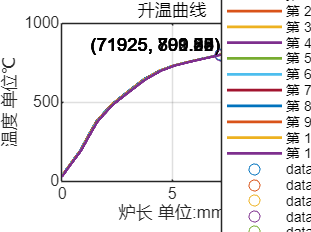

%物料第一层和中间层(最后一层)升温曲线
% % 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
% process_vector = [cellZoneInfo{:,3}] * 1000;
% 
% % 初始化 x 坐标和 y 坐标
% x_total = [];
% y1_total = [];
% y11_total = [];
% 
% % 累积和计算 x 坐标
% x_start = 0;
% for i = 1:length(cellZoneInfo)
%     % 计算当前区间的 x 坐标
%     x_end = x_start + process_vector(i);
%     x = linspace(x_start, x_end, s_timeStep);
%     x_total = [x_total, x];
% 
%     % 创建当前区间的矩阵 
%     matrix = Temp_total(:, 1 + (i-1) * s_timeStep : i * s_timeStep);
% 
%     % 提取第一行和最后一行
%     y1 = matrix(1, :);
%     y11 = matrix(11, :);
% 
%     % 累积 y 坐标
%     y1_total = [y1_total, y1];
%     y11_total = [y11_total, y11];
% 
%     % 更新 x 起点
%     x_start = x_end;
% end
% 
% % 绘制折线图
% figure;
% plot(x_total, y1_total, 'r-', 'LineWidth', 1.5); 
% hold on;
% plot(x_total, y11_total, 'b-', 'LineWidth', 1.5);
% hold on;
% 
% % 添加图例和标签
% legend('表面温度', '中心温度');
% xlabel('炉长 单位:mm');
% ylabel('温度 单位℃');
% title('升温曲线');
% 
% % 显示网格
% grid on;
% 
% % 查找 x = 71925 对应的 y 值
% x_target = 71925;
% [~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引
% y1_target = y1_total(idx);
% y11_target = y11_total(idx);
% 
% % 在图中标注 x = 71925 时对应的 y 值
% plot(x_target, y1_target, 'ro'); % 在表面温度曲线上的标注
% text(x_target, y1_target, sprintf('(%d, %.2f)', x_target, y1_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
% 
% plot(x_target, y11_target, 'bo'); % 在中心温度曲线上的标注
% text(x_target, y11_target, sprintf('(%d, %.2f)', x_target, y11_target), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');
% 
% hold off;



%各层升温曲线
% 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
process_vector = [cellZoneInfo{:,3}] * 1000;

% 初始化 x 坐标和 y 坐标
x_total = [];

% 累积和计算 x 坐标
x_start = 0;
for i = 1:length(cellZoneInfo)
    % 计算当前区间的 x 坐标
    x_end = x_start + process_vector(i);
    x = linspace(x_start, x_end, s_timeStep);
    x_total = [x_total, x];
    x_start = x_end;
end

% 绘制折线图
figure;

% 定义颜色列表
colors = lines(11); % 使用 lines 函数生成颜色

% 绘制每一行的数据
for row = 1:size(Temp_total, 1)
    % 提取当前行的所有区间数据
    y_total = [];
    for i = 1:length(cellZoneInfo)
        % 创建当前区间的矩阵 
        matrix = Temp_total(:, 1 + (i-1) * s_timeStep : i * s_timeStep);
        % 提取当前行数据
        y = matrix(row, :);
        y_total = [y_total, y];
    end
    % 绘制当前行的折线图
    plot(x_total, y_total, 'Color', colors(row, :), 'LineWidth', 1.5);
    hold on;
end

% 添加图例和标签
legend(arrayfun(@(x) sprintf('第 %d 层', x), 1:11, 'UniformOutput', false));
xlabel('炉长 单位:mm');
ylabel('温度 单位℃');
title('升温曲线');

% 显示网格
grid on;

% 查找 x = 71925 对应的 y 值
x_target = 71925;
[~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引

% 在图中标注 x = 71925 时对应的 y 值
for row = 1:size(Temp_total, 1)
    % 提取当前行的所有区间数据
    y_total = [];
    for i = 1:length(cellZoneInfo)
        % 创建当前区间的矩阵 
        matrix = Temp_total(:, 1 + (i-1) * s_timeStep : i * s_timeStep);
        % 提取当前行数据
        y = matrix(row, :);
        y_total = [y_total, y];
    end
    % 获取对应索引处的 y 坐标值
    y_target = y_total(idx);
    % 在折线图上标注
    plot(x_target, y_target, 'o', 'Color', colors(row, :)); 
    text(x_target, y_target, sprintf('(%d, %.2f)', x_target, y_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

hold off;

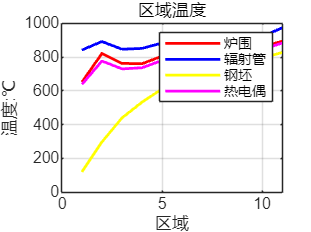





%三元各区域升温曲线
x = linspace(1,11,11);
yTw = Tw_zone - 237.15;
yTr = Tr_zone - 273.15;
yTs = Ts_zone - 273.15;
yTt = Tt_zone - 273.15;

% 绘制折线图
figure;
plot(x, yTw, 'r-', 'LineWidth', 1.5);
hold on;
plot(x, yTr, 'b-', 'LineWidth', 1.5); 
hold on;
plot(x, yTs, 'y-', 'LineWidth', 1.5); 
hold on;
plot(x, yTt, 'm-', 'LineWidth', 1.5); 


% 添加图例和标签
legend('炉围', '辐射管', '钢坯', '热电偶' );
xlabel('区域');
ylabel('温度:℃');
title('区域温度');

% 显示网格
grid on;
hold off;

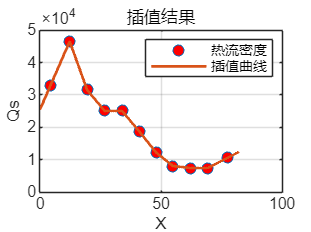



%插值热流密度
% 定义插值点
xInterp = linspace(0, 82.2, 500); % 在范围 (0, 82.2) 内生成 500 个插值点

% 进行插值
% 使用线性插值（'linear'），其他选项有 'spline' 或 'pchip' 等
qInterp = interp1(X, Qs, xInterp, 'linear', 'extrap');

% 绘制原始数据点和插值结果
figure;
plot(X, Qs, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 6); % 原始数据点
hold on;
plot(xInterp, qInterp, '-', 'LineWidth', 1.5); % 插值曲线
hold off;

% 添加标题和标签
title('插值结果');
xlabel('X');
ylabel('Qs');
legend('热流密度', '插值曲线');
grid on;

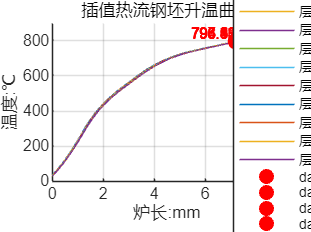





%插值热流升温曲线
% 定义 x 轴的取值范围，从 0 到 82200，分为 s_timeStep * length(cellZoneInfo) 份
xValues = linspace(0, 82200, s_timeStep * length(cellZoneInfo));

% 从第 2 个点开始绘图，所以选择 xValues 的索引 2 到 段尾
xPlot = xValues(2:end);

% 创建一个图形窗口
figure;

% 绘制每一行的数据作为一条曲线
hold on; % 保持绘图，叠加多条曲线
for i = 1:size(Temp_total_2, 1)
    yPlot = Temp_total_2(i, 2:end); % 获取当前行，从第 2 列到最后一列的数据
    plot(xPlot, yPlot, 'DisplayName', sprintf('层 %d', i)); % 绘制曲线
end

% 在 x = 71925 时标注 y 值
xTarget = 71925;
% 找到 xTarget 在 xPlot 中的最近索引
[~, targetIndex] = min(abs(xPlot - xTarget));

% 标注每条曲线在 x = 71925 时的 y 值
for i = 1:size(Temp_total_2, 1)
    yValueAtTarget = Temp_total_2(i, targetIndex + 1); % 获取每行的 y 值
    % 在图上标注点
    plot(xPlot(targetIndex), yValueAtTarget, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 红色圆点标注
    % 在图上标注文字
    text(xPlot(targetIndex), yValueAtTarget, ...
        sprintf('%.2f', yValueAtTarget), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', ...
        'FontSize', 8, 'Color', 'r');
end

hold off;

% 添加图例
legend('show');

% 添加标题和坐标轴标签
title('插值热流钢坯升温曲线');
xlabel('炉长:mm');
ylabel('温度:℃');
grid on;

**函数**

%计算空间角系数
%x为炉宽，m;h为炉高，m;y为炉段长度，m;h1为辐射管上端距炉墙高度，m;h2为辐射管下端距假象面p高度，m
function phi = phi_p1_w2(x, y, h1)
    X = x / h1;
    Y = y / h1;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_s(x, y, h2)
    X = x / h2;
    Y = y / h2;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_w1(x, y, h2)
    H = h2 / y;
    W = x / y;
    
    term1 = W * atan(1 / W) + H * atan(1 / H);
    term2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    term3 = (1 + W^2) * (1 + H^2) / (1 + W^2 + H^2) * (W^2 * (1 + W^2 + H^2) / ((1 + W^2) * (W^2 + H^2)))^(W^2);
    term4 = (H^2 * (1 + H^2 + W^2) / ((1 + H^2) * (H^2 + W^2)))^(H^2);
    phi = (2 / (pi * W)) * (term1 - term2 + 1/4*log(term3 * term4));
end

function phi = phi_p2_w11(x, y, h2)
    % 定义H和W
    H = h2 / y;
    W = x / y;
    
    % 计算第一部分
    part1 = W * atan(1 / W) + H * atan(1 / H);
    
    % 计算第二部分
    part2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    
    % 计算第三部分中的内部分数
    term1_numerator = (1 + W^2) * (1 + H^2);
    term1_denominator = 1 + W^2 + H^2;
    term1 = term1_numerator / term1_denominator;
    
    term2_numerator = W^2 * (1 + W^2 + H^2);
    term2_denominator = (1 + W^2) * (W^2 + H^2);
    term2 = term2_numerator / term2_denominator;
    term2 = term2^(W^2);
    
    term3_numerator = H^2 * (1 + H^2 + W^2);
    term3_denominator = (1 + H^2) * (H^2 + W^2);
    term3 = term3_numerator / term3_denominator;
    term3 = term3^(H^2);
    
    % 计算第三部分
    part3 = (1/4) * log(term1 * term2 * term3);
    
    % 计算最终结果
    phi = (2 / (pi * W)) * (part1 - part2 + part3);
    
end

%全交换面积计算

function SR = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr)
    % 计算 SR
    numerator = -Fr * epsilon_r * Fs * epsilon_s * (-Fw * rho_w * Xwr * Xws + Fs * Xsr * (-1 + rho_w * Xww));
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SR = numerator / denominator;
end

function SW = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww)
    % 计算 SW
    numerator = Fw * epsilon_w * Fs * epsilon_s * (Fs * rho_r * Xsr * Xwr + Fr * (1 - rho_r * Xrr) * Xws);
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SW = numerator / denominator;
end

function WR = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww)
    % 计算 WR
    numerator = Fr * epsilon_r * Fw * epsilon_w * (Fs * rho_s * Xsr * Xsw + Fw * Xwr);
    denominator = -Fr * (-1 + rho_r * Xrr) * (Fs * rho_s * rho_w * Xsw^2 + Fw * (-1 + rho_w * Xww)) ...
                  + Fw * rho_r * (Fw * rho_w * Xwr^2 + Fs * rho_s * Xsr * (Xsr + 2 * rho_w * Xsw * Xwr - rho_w * Xsr * Xww));
    WR = -numerator / denominator;
end

%TDMA求解表面显示中心隐式差分
%热流 离散层数 密度 时间步长 空间步长 上一时刻温度场
function T = TDMA_s(Qcon,N,density,delta_t,delta_x,T)
    %初始化
    Cp_point = zeros(1,N+1);
    Lambda_point = zeros(1,N+1);

    for i = 1 : N+1
        [Cp_point(i) , Lambda_point(i)] = calPhysicalParameters(1 , T(i));
    end
    Cp_layer = computeAdjacentAverages(Cp_point);
    Lambda_Layer = computeAdjacentHarmonicAverages(Lambda_point);
    Fo = Lambda_Layer./(density.*Cp_layer)*delta_t/(delta_x^2);
    
    %边界节点计算
    T(1) = T(1) + 2*Fo(1)*(T(2) - T(1) + Qcon*delta_x/Lambda_Layer(1));
    T(N+1) = T(N+1) + 2*Fo(N)*(T(N) - T(N+1));

    %Thomas算法内部节点计算
    a = -Fo(2:N-1);
    b = 1 + computeAdjacentSums(Fo);
    c = -Fo(2:N-1);
    d = T(2:N);
    d(1) = d(1) + Fo(1) * T(1);
    d(N-1) = d(N-1) + Fo(N) * T(N+1);
    
    x = tridiagonal_vector(a,b,c,d);%三对角矩阵算法
    % 检查向量长度以确保可以替换
    if length(T) < 2 || length(x) ~= length(T) - 2
        error('向量 T 和 x 的长度不匹配，无法进行替换');
    end
    % 替换 T 的第 2 到第 N 个元素为 x 的第 1 到第 N-1 个元素
    T(2:end-1) = x;
end


%计算相邻两元素的算术平均值
function avgArray = computeAdjacentAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    avgArray = zeros(1, n-1);

    % 计算相邻元素的算术平均值
    for i = 1:n-1
        avgArray(i) = (inputArray(i) + inputArray(i+1)) / 2;
    end
end


%计算相邻两元素的调和平均值
function harmonicAvgArray = computeAdjacentHarmonicAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的调和平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    harmonicAvgArray = zeros(1, n-1);

    % 计算相邻元素的调和平均值
    for i = 1:n-1
        harmonicAvgArray(i) = 2 / (1/inputArray(i) + 1/inputArray(i+1));
    end
end

%计算两相邻元素的加和
function sumArray = computeAdjacentSums(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的和
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    sumArray = zeros(1, n-1);

    % 计算相邻元素的和
    for i = 1:n-1
        sumArray(i) = inputArray(i) + inputArray(i+1);
    end
end

%计算热电偶角系数
function Fd1_2 = computeF(a, b, c)
    % Compute X and Y based on the input parameters a, b, and c
    X = b / c;
    Y = a / c;
    
    % Calculate Fd1_2 using the provided formula
    Fd1_2 = (1 / (4 * pi)) * atan(X * Y / sqrt(1 + X^2 + Y^2));
end

%计算区域中点坐标
function X = computeX(inputArray)
    X = zeros(1,length(inputArray));
    for i = 1:length(inputArray)
        process_Array = inputArray(1:i-1);
        X(i) = inputArray(i)*1/2 + sum(process_Array);
    end
end

%插值热流函数
function qInterp = interpolateQs(Qs,X,xValues)
    % 使用插值法计算 qInterp
    qInterp = interp1(X, Qs, xValues, 'linear', 'extrap');
end

